LAB 01 de EET-51

(a) Implemente uma função no MatLab para calcular o limitante superior da probabilidade de erro de símbolo para o 8-PSK. Plote o resultado em função de , dentro de um intervalo de 0 − − − 13 dB.

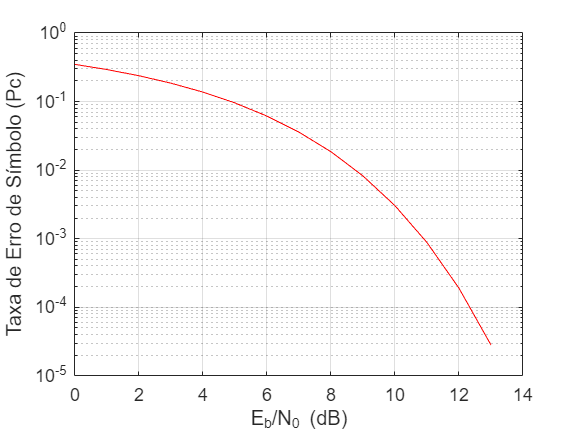

clear; clc;
format long;

EbN0dB = 0:1:13;
EbN0 = 10.^(EbN0dB/10);
M = 8;
Pc = 2*qfunc(sqrt(2*EbN0*log2(M))*sin(pi/M));

figure(1)
semilogy(EbN0dB,Pc,'r');
xlabel('E_b/N_0 (dB)');
ylabel('Taxa de Erro de Símbolo (Pc)');
grid on;

(b) Implemente uma função que gera aleatoriamente 1 milhão de símbolos recebidos, corrompidos por uma sequência de vetores gaussianos. Utilize o critério de mínima distância para recuperar os símbolos e calcule a taxa de erro de símbolo do 8-PSK operando com demodulação coerente. Considerando que Es = 1, ajuste o valor de N0 e calcule a taxa de erro para , dentro de um intervalo de 0−−−13 dB. Compare os valores obtidos com o resultado do item (a).

rng('default'); % Semente aleatória para replicabilidade

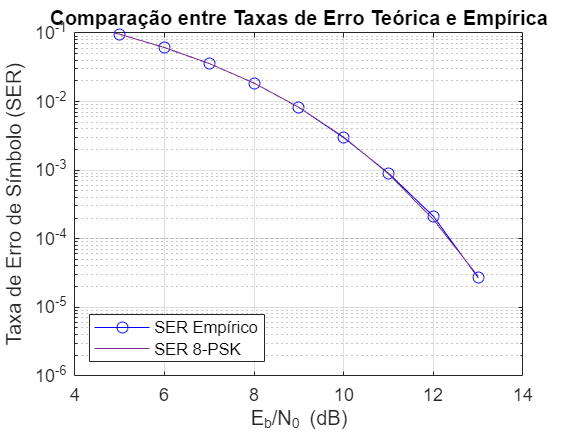

b = 3e6;    % Total de bits
EbN0dB = 0:1:13;
EbN0 = 10.^(EbN0dB/10);
Pe = zeros(1,length(EbN0dB));

%% 8-PSK
M = 8;                                       % Símbolos
k = log2(M);                                 % Bits por símbolo
symb = [1, exp(pi*1j/4), 1j, exp(pi*3j/4), -1, exp(pi*5j/4), -1j, exp(pi*7j/4)];    % Símbolos
m = randi([0, 1], 1, b);                     % Sinal: Vetor de bits aleatórios 0 ou 1
s = zeros(1,b/k);

% % SER teórico para o 8-PSK
% ser8psk = 2 * qfunc(sqrt(2*k*EbN0)*sin(pi/M)); % Limitante superior

for l = 1:b/k                                % Código de Gray
    p = m(3*l-2:3*l);
    if isequal(p,[0 0 0])
        s(l) = symb(1);
    elseif isequal(p,[0 0 1])
        s(l) = symb(2);
    elseif isequal(p,[1 0 1])
        s(l) = symb(3);
    elseif isequal(p,[1 1 1])
        s(l) = symb(4);
    elseif isequal(p,[0 1 1])
        s(l) = symb(5);
    elseif isequal(p,[0 1 0])
        s(l) = symb(6);
    elseif isequal(p,[1 1 0])
        s(l) = symb(7);
    elseif isequal(p,[1 0 0])
        s(l) = symb(8);
    end
end

for i = length(EbN0dB):-1:1  % Monte Carlo
    % Ruído: media + sigma .* rand(1, b), com media = 0 e sigma proporcional a sqrt(0.5/EbN0);
    r = s + (sqrt(0.5/EbN0(i)) * randn(1, b/k) + sqrt(0.5/EbN0(i)) * randn(1, b/k) * 1j) / sqrt(3);       % Sinal com ruído
    for p = 1:b/k                     % Decisor
        [~, index] = min([abs(r(p)-symb(1)), abs(r(p)-symb(2)), abs(r(p)-symb(3)), abs(r(p)-symb(4)), ...
            abs(r(p)-symb(5)), abs(r(p)-symb(6)), abs(r(p)-symb(7)), abs(r(p)-symb(8))]);
        r(p) = symb(index);
    end
    Pe(i) = k * nnz(r-s) / b;
end

semilogy(EbN0dB,Pe,'bo-');
xlabel('E_b/N_0 (dB)');
ylabel('Taxa de Erro de Símbolo (SER)');
grid on;
ylim([1e-6, 0.1])
hold on;
semilogy(EbN0dB, Pc, 'color', [0.4940, 0.1840, 0.5560]);
set(legend, 'Location', 'southwest');
legend('SER Empírico','SER 8-PSK');
title('Comparação entre Taxas de Erro Teórica e Empírica');
hold off;

(c) Repita o item (b), considerando um sistema DPSK, com oito símbolos e demodulação não coerente. No seu programa, escolha um valor aleatório para a fase θ.

rng('default'); % Semente aleatória para replicabilidade

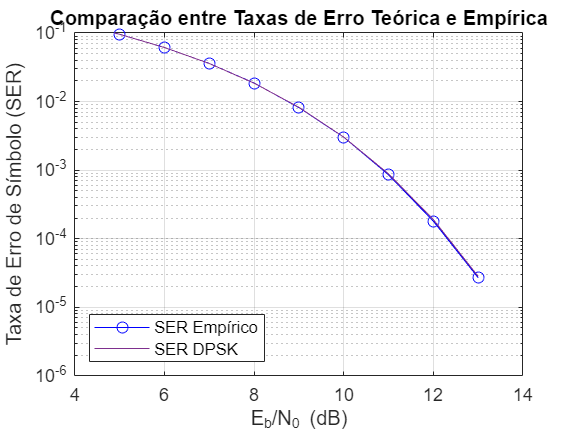

b = 3e6;    % Total de bits
EbN0dB = 0:1:13;
EbN0 = 10.^(EbN0dB/10);
Ped = zeros(1,length(EbN0dB));

%% DPSK
M = 8;  % Símbolos
k = log2(M);    % Bits por símbolo
theta = pi/3;
symb = exp(1j*theta)*[1, exp(pi*1j/4), 1j, exp(pi*3j/4), -1, exp(pi*5j/4), -1j, exp(pi*7j/4)];    % Símbolos
m = randi([0, 1], 1, b);    % Sinal: Vetor de bits aleatórios 0 ou 1
s = zeros(1,b/k);

% % SER teórico para o 8-PSK
% ser8psk = 2 * qfunc(sqrt(2*k*EbN0)*sin(pi/M)); % Limitante superior

for l = 1:b/k                                % Código de Gray
    p = m(3*l-2:3*l);
    if isequal(p,[0 0 0])
        s(l) = symb(1);
    elseif isequal(p,[0 0 1])
        s(l) = symb(2);
    elseif isequal(p,[1 0 1])
        s(l) = symb(3);
    elseif isequal(p,[1 1 1])
        s(l) = symb(4);
    elseif isequal(p,[0 1 1])
        s(l) = symb(5);
    elseif isequal(p,[0 1 0])
        s(l) = symb(6);
    elseif isequal(p,[1 1 0])
        s(l) = symb(7);
    elseif isequal(p,[1 0 0])
        s(l) = symb(8);
    end
end

for i = length(EbN0dB):-1:1  % Monte Carlo
    % Ruído: media + sigma .* rand(1, b), com media = 0 e sigma proporcional a sqrt(0.5/EbN0);
    r = s + (sqrt(0.5/EbN0(i)) * randn(1, b/k) + sqrt(0.5/EbN0(i)) * randn(1, b/k) * 1j) / sqrt(3); % Sinal com ruído
    for p = 1:b/k                     % Decisor
        [~, index] = min([abs(r(p)-symb(1)), abs(r(p)-symb(2)), abs(r(p)-symb(3)), abs(r(p)-symb(4)), ...
            abs(r(p)-symb(5)), abs(r(p)-symb(6)), abs(r(p)-symb(7)), abs(r(p)-symb(8))]);
        r(p) = symb(index);
    end
    Ped(i) = k * nnz(r-s) / b;
end

semilogy(EbN0dB,Ped,'bo-');
xlabel('E_b/N_0 (dB)');
ylabel('Taxa de Erro de Símbolo (SER)');
grid on;
ylim([1e-6, 0.1])
hold on;
semilogy(EbN0dB, Pc, 'color', [0.4940, 0.1840, 0.5560]);
set(legend, 'Location', 'southwest');
legend('SER Empírico','SER DPSK');
title('Comparação entre Taxas de Erro Teórica e Empírica');
hold off;


Teste

Unrecognized function or variable 'Teste'.

M = 8;                 % Modulation order
k = log2(M);            % Bits per symbol
EbNoVec = (0:13);      % Eb/No values (dB)
numSymPerFrame = 1e6;   % Number of QAM symbols per frame

snrdB = convertSNR(EbNoVec,"ebno","snr",BitsPerSymbol=k);

berEst = zeros(size(EbNoVec));

for n = 1:length(snrdB)
    % Reset the error and bit counters
    numErrs = 0;
    numBits = 0;
    
    while numErrs < 200 && numBits < 1e7
        % Generate binary data and convert to symbols
        dataIn = randi([0 1],numSymPerFrame*k,1);
        dataSym = bit2int(dataIn,k);
        
        % DPSK modulate using 'Gray' symbol mapping
        txSig = dpskmod(dataSym,M);
        
        % Pass through AWGN channel
        rxSig = awgn(txSig,snrdB(n),'measured');
        
        % Demodulate the noisy signal
        rxSym = dpskdemod(rxSig,M);
        % Convert received symbols to bits
        dataOut = int2bit(rxSym,k);
        
        % Calculate the number of bit errors
        nErrors = biterr(dataIn,dataOut);
        
        % Increment the error and bit counters
        numErrs = numErrs + nErrors;
        numBits = numBits + numSymPerFrame*k;
    end
    
    % Estimate the BER
    berEst(n) = numErrs/numBits;
end

berTheory = berawgn(EbNoVec,'qam',M);

semilogy(EbNoVec,berEst,'*')
hold on
semilogy(EbNoVec,berTheory)
grid
legend('Estimated BER','Theoretical BER')
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')